# Analyzing Satellite Images of a Flood

Included in the course files are two satellite images of the Mississippi River, one taken before a flood and one taken after. You can determine the increase in area covered with water using the image processing techniques you've learned so far.

### Import and display the images

First, import and examine both images.

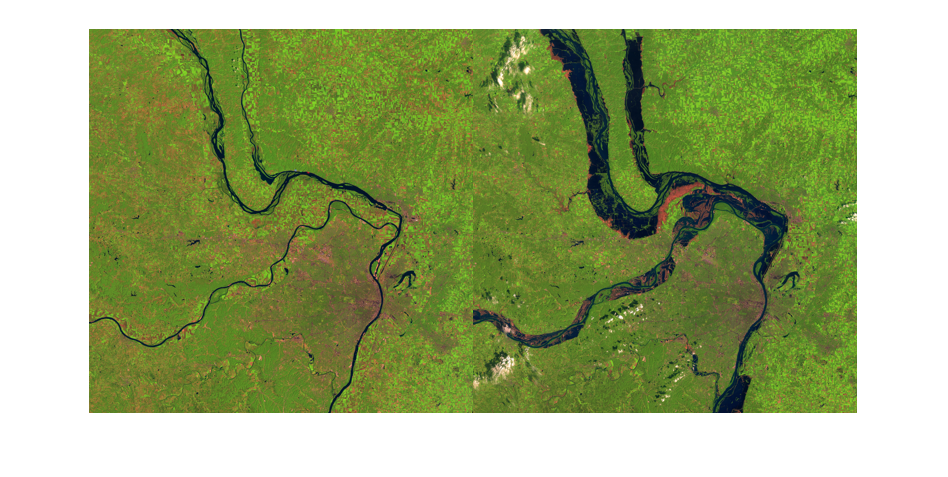

preflood = imread("stlouis_l5tm_14aug91_30m.jpg");
postflood = imread("stlouis_l5tm_19aug93_30m.jpg");
montage({preflood,postflood})

You can immediately see the amount of water changed a lot, but by how much? 

### Color thresholding

Go to the Color Thresholding App and import the preflood image. Try to segment out the dark blue river areas. 

After you are satisfied with your segmentation in the app, export the function and check that it works on the other image. If the mask doesn't look how you expected, go back and refine your segmentation function. If you get stuck, see the hint at the bottom of this script.

Insert your segmentation function below with the preflood image as input and uncomment the lines. Use the provided variable names since they will be used in the rest of the script.

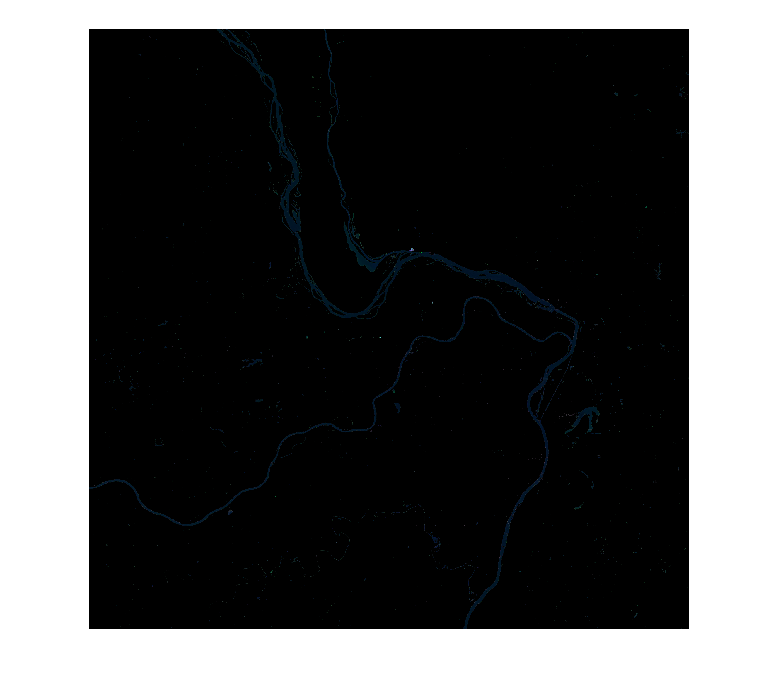

 [BWpre, maskpre] = HSV_SPACE_EXPORT(preflood);
 imshow(maskpre)

Now do the same thing for the postflood image.

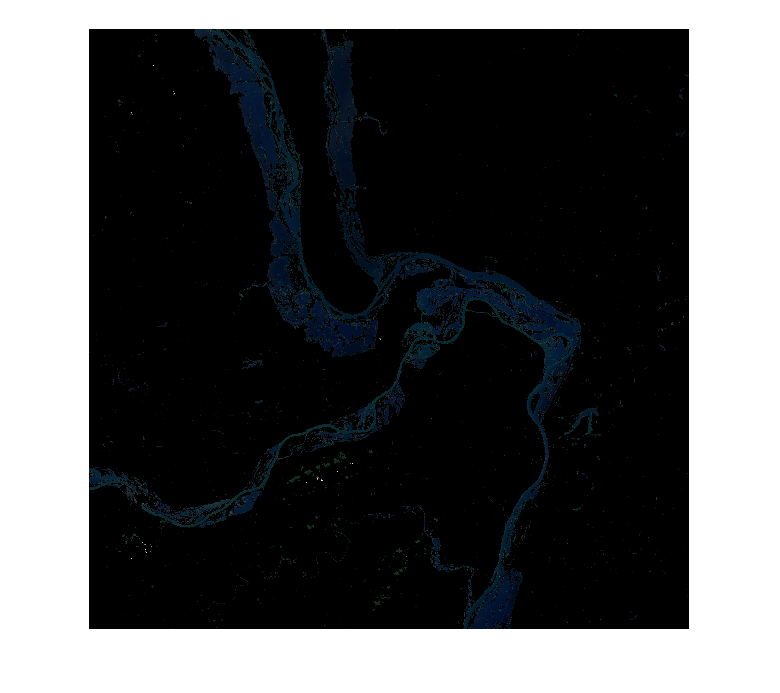

 [BWpost, maskpost] = HSV_SPACE_EXPORT(postflood);
 imshow(maskpost)

### Numerical analysis

Use the segmentation function outputs and the `nnz` function to calculate the number of blue river pixels in each image. Let's take a look at the results. 

nnz(BWpre)

ans = 321738

nnz(BWpost)

ans = 1205659

Your results for the preflood image should be between 250,000 and 290,000, and your results for the postflood image should be between 1,000,000 and 1,100,000. If your results do not fall within this range, you should try going back and further refining your segmentation function.

Finally, calculate the increase in pixel values between the first and second images.

(nnz(BWpost) - nnz(BWpre)) / nnz(BWpre) * 100

ans = 274.7332

You should be seeing a value of around 277%. That's a huge increase in water area due to the flood! 

### Hint for segmenting the images

*Spoiler Alert*! Try segmenting the images yourself first, but if you get stuck, use the screenshot below to help you find an appropiate threshold.

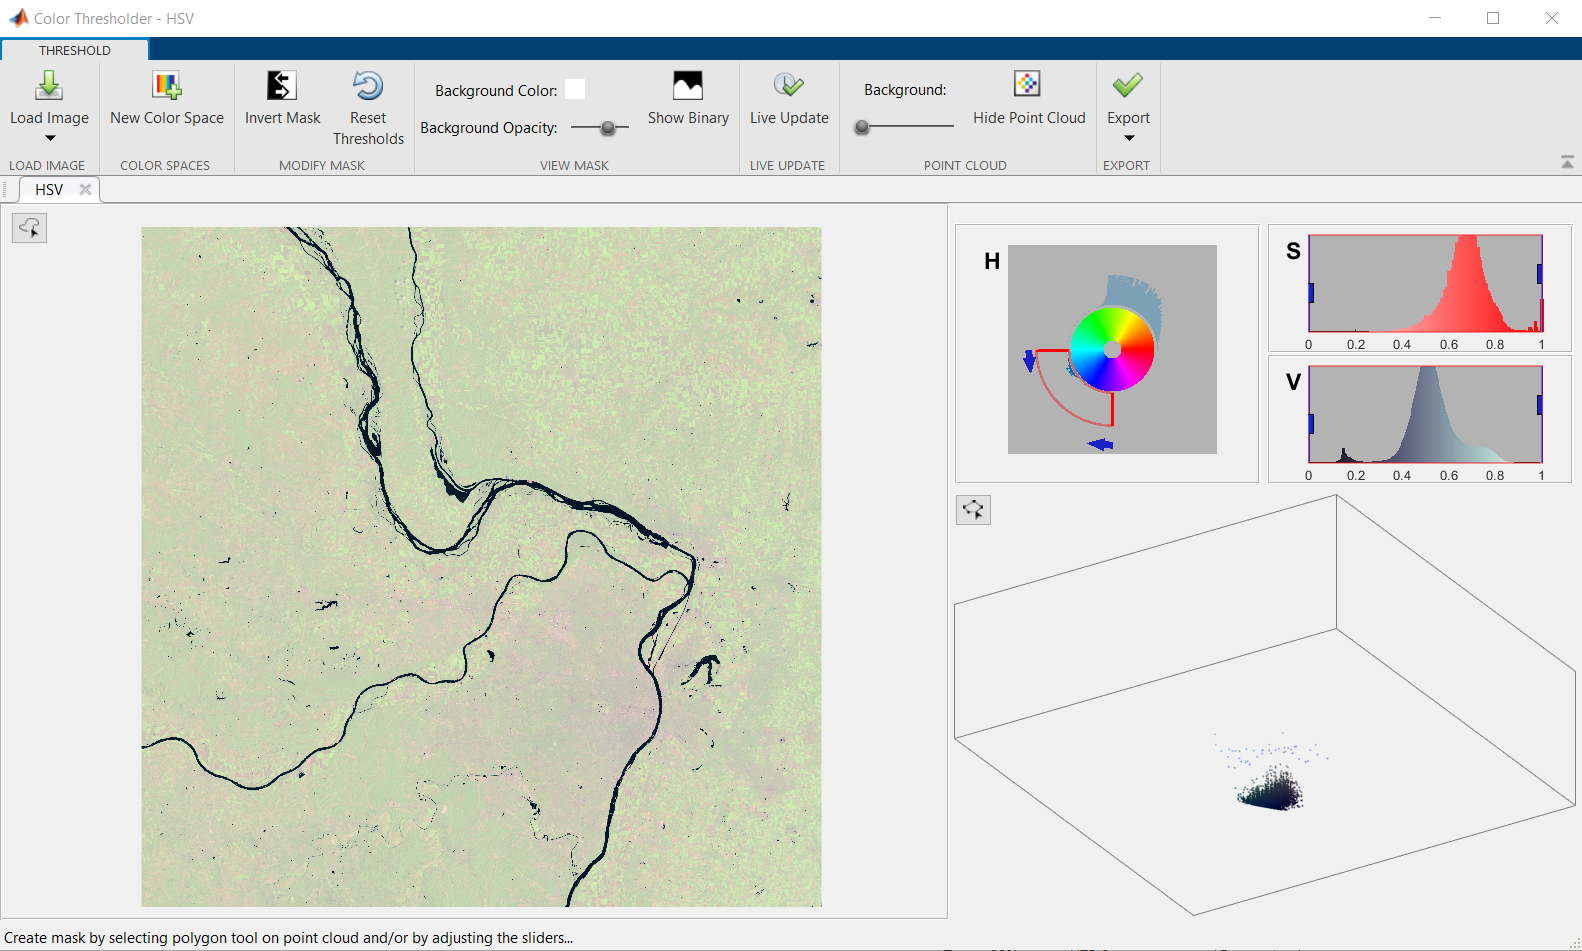

*Copyright 2022 The MathWorks, Inc.*